# Sunflower Seeds

The Fibonacci sequence can give us some insight into sunflower seeds.

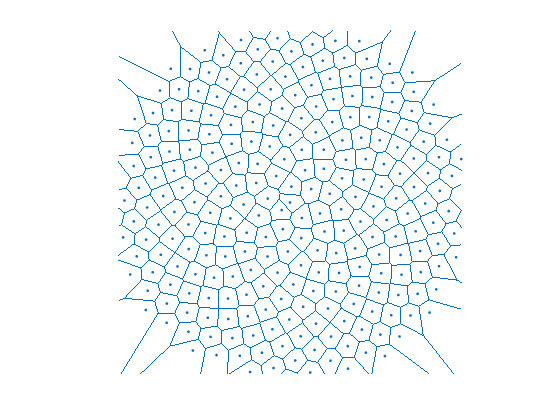

% phi = (sqrt(5)+1)/2;
% c = phi;

c = 1.618;
d = 2*pi/c;
theta = 0:d:1000;
r = sqrt(theta);
[x,y] = pol2cart(theta,r);

voronoi(x,y)

axis square
axis(30*[-1 1 -1 1])
axis off

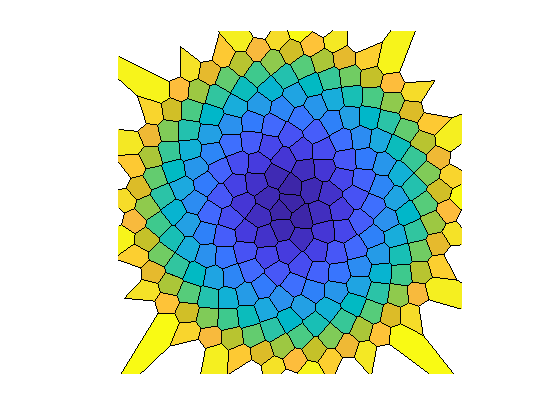

c = 1.618;
d = 2*pi/c;
theta = 0:d:1000;
r = sqrt(theta);
[x,y] = pol2cart(theta,r);

[v,c] = voronoin([x',y']);
cla
for i = 1:length(c)
    if all(c{i}~=1)
        % If at least one index is 1, then it is an open region and we can't patch it
        xp = v(c{i},1);
        yp = v(c{i},2);
        % use color i.
        patch(xp,yp,i);
    end
end

axis square
axis(30*[-1 1 -1 1])
axis off